## EBS 221 Agricultural Robotics

## Spring Quarter 2025

### **Assignment 1**

#### Please submit a single assignment file (either PDF or Word) along with all necessary Matlab files to reproduce the results. This is a group assignment, so each team will submit one report (including the source code). The grade will also be the same for all team members. 

#### **A. **(60 pts) Implement the bicycle model with 1st -order closed-loop steering and speed dynamics in a MATLAB function called robot_bike_dyn(). Use global variables for dt, DT (case-sensitive).

    function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)

    global dt; global DT;

    model of a vehicle with closed-loop steering and velocity control

    the combined effect of steering/vehicle inertia and control is a first order system for steering     (tau_gamma) and velocity (tau_v) state is vector q 

    % q(1) -> x

    % q(2) -> y

    % q(3) -> theta (orientation in world frame) 

    % q(4) -> gamma (steering angle)

    % q(5) -> v (linear velocity)

    % inputs are: % u(1) -> desired steering angle (gamma_d) % u(2) -> desired linear velocity (v_d) 

#### **Section A: Bicycle Model Dynamics **

#### In this section, we implement the dynamics of a robotic vehicle using the bicycle kinematic model with first-order closed-loop steering and velocity control. 

#### This model is suitable for many ground robots and autonomous vehicles that can be approximated by a two-wheel configuration. 

#### **Function Overview **

#### The MATLAB function `robot_bike_dyn` computes the next state of the robot given the current state `q`, desired control input `u`, and model parameters. 

#### It incorporates actuation delays through first-order filters (controlled by `tau_gamma` and `tau_v`), and uses Euler integration. 

#### **Equation Summary** 

#### The robot state vector q = [x; y; theta; gamma; v] 

#### where: 

####   x, y         - position in world frame 

####   theta       - orientation angle 

####   gamma   - steering angle 

####   v             - linear velocity 

#### The control inputs u = [gamma_d; v_d] are: 

####   gamma_d  - desired steering angle 

####   v_d      - desired velocity 

#### **MATLAB Function:** robot_bike_dyn.m 

#### The function implements: 

####   - First-order lag filters: 

####         dgamma = (gamma_d - gamma) / tau_gamma 

####         dv     = (v_d - v) / tau_v 

####   - Kinematic update: 

####         dx     = v * cos(theta) 

####         dy     = v * sin(theta) 

####         dtheta = v * tan(gamma) / L 

####   - Euler integration: 

####         q_next = q + dt * dq 

#### **Code from robot_bike_dyn.m is provided below with comments **

%% Function file robot_bike_dyn.m content commented below for reference.
function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt;
    global DT;

    % Extract current state
    x     = q(1);
    y     = q(2);
    theta = q(3);
    gamma = q(4);
    v     = q(5);

    % Desired inputs
    gamma_d = u(1); % desired steering angle
    v_d     = u(2); % desired velocity

    % Input saturation
    gamma_d = max(min(gamma_d, umax(1)), umin(1));
    v_d     = max(min(v_d, umax(2)), umin(2));

    % Handle zero time constants (instantaneous control)
    if tau_gamma == 0
        gamma = gamma_d;
        dgamma = 0;
    else
        dgamma = (gamma_d - gamma) / (tau_gamma + 1e-12);
    end

    if tau_v == 0
        v = v_d;
        dv = 0;
    else
        dv = (v_d - v) / (tau_v + 1e-12);
    end

    % Euler integration for control states
    gamma = gamma + dt * dgamma;
    v     = v + dt * dv;

    % Kinematic update using bicycle model
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;

    % Euler integration for pose
    x     = x + dt * dx;
    y     = y + dt * dy;
    theta = theta + dt * dtheta;

    % Saturate state variables
    x     = max(min(x, Qmax(1)), Qmin(1));
    y     = max(min(y, Qmax(2)), Qmin(2));
    theta = max(min(theta, Qmax(3)), Qmin(3));
    gamma = max(min(gamma, Qmax(4)), Qmin(4));
    v     = max(min(v, Qmax(5)), Qmin(5));

    % Return updated state
    q_next = [x; y; theta; gamma; v];
end

#### **Why First-Order Filters?**

#### In real vehicles, the steering mechanism and velocity controller don't respond instantaneously. The first-order filters in `robot_bike_dyn` model the system's actuation dynamics.

#### **Why Euler Integration?**

#### Euler integration is computationally simple and sufficient for small time steps (`dt`).

#### **Control Constraints**

#### Saturation of both inputs and states ensures that the robot stays within physical limits (e.g., max turning angle or speed).

% % Debugging section:
% 
% % Set global timestep
% global dt DT;
% dt = 0.1;     % integration time step
% DT = 0.1;     % not used in current code, but declared
% 
% % Initial state: [x; y; theta; v; gamma]
% q = [0; 0; 0; 0; 0];
% 
% % Desired inputs: [gamma_d; v_d]
% u = [0.2; 1.0];  % 0.2 rad steering, 1 m/s velocity
% 
% % Input limits: [gamma_min, v_min], [gamma_max, v_max]
% umin = [-0.5; 0];
% umax = [0.5; 5.0];
% 
% % State limits: [x, y, theta, v, gamma]
% Qmin = [-Inf; -Inf; -pi; 0; -0.5];
% Qmax = [ Inf;  Inf;  pi; 2;  0.5];
% 
% % Vehicle parameters
% L = 2.5;              % wheelbase in meters
% tau_gamma = 0.5;      % steering response time (s)
% tau_v = 0.8;          % velocity response time (s)
% 
% % Call the function
% q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v);
% 
% % Display next state
% disp('Next state:');
% disp(q_next);

% %% Debugging section:
% N = 500;
% Q = zeros(5, N);
% Q(:,1) = q;
% 
% for k = 2:N
%     Q(:,k) = robot_bike_dyn(Q(:,k-1), u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v);
% end
% 
% % Plot trajectory
% plot(Q(1,:), Q(2,:), 'b.-');
% xlabel('x'); ylabel('y'); title('Robot trajectory');
% axis equal;


#### **B.** (20 pts) In a script file, set the wheelbase L = 2.5 m; |γmax| = π/4o, and |vmax| = 5 m/s. Set dt=0.01 s, DT=0.1 s, 𝑣𝑑=1 m/s. Start at the state [10 10 π/2].

#### Apply appropriate steering input 𝛾𝑑(𝑡𝑘) for an appropriate amount of time T, to travel on a semicircle of radius 3 m. (This simulates turning in a field with row crops from the exit of

#### one row to the entrance of the next row, and a row-center distance of 6 m.) Plot the semicircle and the actual motion trace (i.e., x(tk), y(tk)).

#### Repeat for a radius of 2 m. Does it work? Why?

#### **Section B: Simulating the Bicycle Model **

#### In this section, we simulate the robot's motion over time using the bicycle dynamics model implemented in Section A. We visualize how the robot responds  to a fixed control input using first-order closed-loop dynamics.

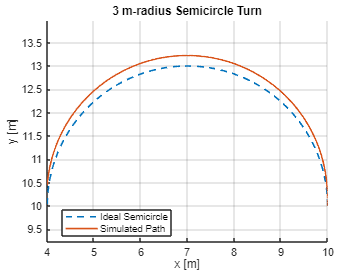

%% Section B: Semicircle Path Simulation

% Parameters Setup
L          = 2.5;                 % Wheel-base length [m]
gamma_max  = pi/4;                % Maximum steering angle [rad] (45°)
v_max      = 5;                   % Maximum velocity [m/s]
dt         = 0.01;                % Integration step [s]
DT         = 0.10;                % Sample interval (unused here)
vd         = 1.0;                 % Desired velocity [m/s]

global dt DT                      % Required globals for dynamics function

% Desired radius and steering calculation (R = 3 m)
R = 3.0;
gamma_cmd = atan(L/R);
assert(gamma_cmd <= gamma_max, 'γ_d exceeds γ_max!')

% Simulation time (half-circle trajectory)
T = pi*R / vd;
Nsteps = ceil(T/dt);

% Limits
Qmin  = [-Inf -Inf -Inf -gamma_max 0];
Qmax  = [ Inf  Inf  Inf  gamma_max v_max];
umin  = [-gamma_max -v_max];
umax  = [ gamma_max  v_max];

% Initial state [x, y, θ, γ, v]
q = [10; 10; pi/2; 0; vd];

% Storage for trajectory trace
trail = zeros(Nsteps+1,2);
trail(1,:) = q(1:2).';

% Simulation loop
for k = 1:Nsteps
    u = [gamma_cmd; vd];
    q = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, 0.2, 0.5);
    trail(k+1,:) = q(1:2).';
end

% Plotting results
figure; hold on; axis equal; grid on;
title('3 m-radius Semicircle Turn');
xlabel('x [m]');
ylabel('y [m]');

% Ideal semicircle
phi = linspace(0, pi, 181);
xc = 10 - R; yc = 10;
plot(xc + R*cos(phi), yc + R*sin(phi), '--', 'LineWidth', 1.5);

% Simulated trajectory
plot(trail(:,1), trail(:,2), 'LineWidth', 1.5);
legend('Ideal Semicircle', 'Simulated Path', 'Location', 'best');

#### **Plot Commentary:**

#### **Blue dashed curve**: The *ideal semicircle*, calculated analytically with radius `R`.

#### **Red solid curve**: The *simulated robot trajectory*, computed using the `robot_bike_dyn` model with steering lag and velocity lag.

#### **For R = 3 m:** The robot closely follows the ideal path, since the required steering angle is within feasible limits (|γ| ≤ π/4).

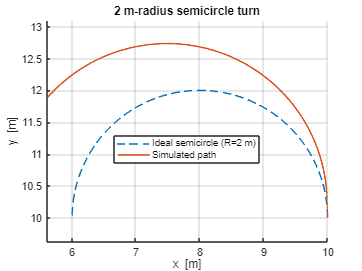

% ─────────────────────────
% Desired radius and steering calculation (R = 2 m)
R          = 2.0;                 % requested radius [m]
gamma_cmd  = atan(L/R);

% Simulation horizon: half‑circumference  s = πR  so  T = s / v
T          = pi*R / vd;
Nsteps     = ceil(T/dt);

% State limits (set very large so they never clip)
Qmin  = [-Inf -Inf -Inf  -gamma_max      0];
Qmax  = [ Inf  Inf  Inf   gamma_max   v_max];
umin  = [-gamma_max  -v_max];
umax  = [ gamma_max   v_max];

% Initial state: rear‑axle at (10,10), heading +y  (θ = π/2)
q      = [10; 10; pi/2; 0; vd];                  % [x y θ γ v]

% Storage for trace
trail  = zeros(Nsteps+1,2);
trail(1,:) = q(1:2).';

% Main simulation loop
for k = 1:Nsteps
    u        = [gamma_cmd; vd];                 % constant inputs
    q        = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, 0.2, 0.5);     % τ_γ=0.2 s, τ_v=0.5 s
    trail(k+1,:) = q(1:2).';
end

% Plot ideal semicircle and the driven path
figure, hold on, axis equal, grid on
xlabel('x  [m]'), ylabel('y  [m]'), title('2 m‑radius semicircle turn')

% Ideal semicircle (left‑hand turn, centre at (7,10))
phi  = linspace(0,pi,181);                      % 0 -> 180°
xc   = 10 - R;  yc = 10;                        % centre coords
plot(xc + R*cos(phi), yc + R*sin(phi), '--');   % ideal path

% Simulated trace
plot(trail(:,1), trail(:,2), 'LineWidth',1.5);

legend('Ideal semicircle (R=2 m)', 'Simulated path','Location','best')

#### **Plot Commentary:**

#### **Blue dashed curve**: The *ideal semicircle*, calculated analytically with radius `R`.

#### **Red solid curve**: The *simulated robot trajectory*, computed using the `robot_bike_dyn` model with steering lag and velocity lag.

#### **For R = 2 m**: The simulated path **deviates** noticeably from the ideal semicircle — as your figure shows, it overshoots and ends up outside the ideal curve.

#### **Why does R = 2 m not work well?**

#### **Kinematic Limitations**

#### The required steering angle for a 2 m radius turn:

#### 
$$
$$\gamma_d = \tan^{-1}\left(\frac{L}{R}\right) = \tan^{-1}\left(\frac{2.5}{2}\right) \approx 51.3^\circ > \gamma_{\text{max}} = 45^\circ$$$$


#### So, **the robot cannot physically achieve that curvature**, even with perfect tracking.

#### **Actuation Lag**

#### Even if the steering limit were slightly extended, the system still experiences a **lag** in reaching the commanded steering value due to the nonzero `τ_γ`. This further increases the tracking error.

#### **Conclusion**

#### The 3 m radius turn is feasible and well-tracked.

#### The 2 m radius turn violates hardware limits (|γ| > π/4), making it **infeasible** under current constraints.

#### **C. **(20 pts) Plot the trace of the origin of the vehicle’s frame when γd(tk) starts at 0 and remains 0 for 1s, then switches instantaneously to γmax (step function) and remains at γmax for 10 seconds, then switches instantaneously from γmax to -γmax and stays at -γmax for 10 seconds. Use the following settings.

#### 1.    Speed lag: set to τv = 0 s, increase τγ from 0 to 2 s with a step of 0.4 s, and plot the six traces in the same figure.

#### 2.    Speed lag: set to τv = 1 s, and increase τγ from 0 to 2 s with a step of 0.4 s, and plot the six traces in the same figure.

#### (Think how you will implement τv or τγ = 0.) Comment on these plots.

#### **Section C: Trajectory Under Step Steering Input with Varying Time Constants**

#### We simulate the response of the robot to a step change in steering input γ_d(t), and observe how the time constants τ_γ (steering lag) and τ_v (velocity lag) affect the path traced by the origin of the robot's frame.

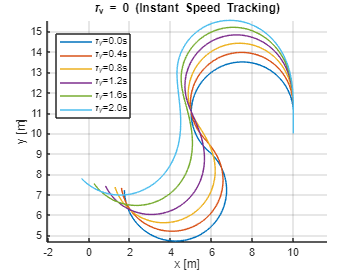

% clear;
% clc;

% function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
%     global dt; 
%     global DT;
% 
%     % Extract current state
%     x     = q(1);
%     y     = q(2);
%     theta = q(3);
%     gamma = q(4);
%     v     = q(5);
% 
%     % Desired inputs
%     gamma_d = u(1);  % desired steering angle
%     v_d     = u(2);  % desired velocity
% 
%     % Saturate desired inputs
%     gamma_d = max(min(gamma_d, umax(1)), umin(1));
%     v_d     = max(min(v_d, umax(2)), umin(2));
% 
%     % treat zero lags as instantaneous tracking
%     if tau_gamma == 0,  gamma = gamma_d;  dgamma = 0;  end
%     if tau_v     == 0,  v     = v_d;      dv     = 0;  end
% 
%     % First-order dynamics for steering and velocity
%     epsLag = 1e-12;                 % small positive number
%     dgamma = (gamma_d - gamma)/(tau_gamma + epsLag);
%     dv     = (v_d     - v    )/(tau_v     + epsLag);
% 
% 
%     % Euler integration to update gamma and v
%     gamma = gamma + dt * dgamma;
%     v     = v + dt * dv;
% 
%     % Bicycle model kinematics
%     dx     = v * cos(theta);
%     dy     = v * sin(theta);
%     dtheta = v * tan(gamma) / L;
% 
%     % Euler integration to update pose
%     x     = x + dt * dx;
%     y     = y + dt * dy;
%     theta = theta + dt * dtheta;
% 
%     % Saturate state vector
%     x     = max(min(x, Qmax(1)), Qmin(1));
%     y     = max(min(y, Qmax(2)), Qmin(2));
%     theta = max(min(theta, Qmax(3)), Qmin(3));
%     gamma = max(min(gamma, Qmax(4)), Qmin(4));
%     v     = max(min(v, Qmax(5)), Qmin(5));
% 
%     % Pack next state
%     q_next = [x; y; theta; gamma; v];
% end

%% Section C: Step Input Response Analysis

% Define simulation parameters
L          = 2.5;
gamma_max  = pi/4;
v_cmd      = 1.0;
dt         = 0.01;
DT         = 0.1;
T_total    = 21.0;            % 1 + 10 + 10 seconds
steps      = round(T_total/dt);
t          = (0:steps)*dt;

% Limits setup
umin  = [-gamma_max -Inf];
umax  = [ gamma_max  Inf];
Qmin  = [-Inf -Inf -Inf -gamma_max 0];
Qmax  = [ Inf  Inf  Inf  gamma_max 5];

% Steering input profile (step function)
gamma_d_profile = @(tk) ...
    (tk < 1) .* 0 + ...
    (tk >= 1 & tk < 11) .* gamma_max + ...
    (tk >= 11) .* (-gamma_max);

% Define lag lists
tau_g_list = 0 : 0.4 : 2;

% 1. τ_v = 0 (instantaneous speed tracking)
figure; hold on; grid on; axis equal;
title('\tau_v = 0 (Instant Speed Tracking)');
xlabel('x [m]'); ylabel('y [m]');

for tau_g = tau_g_list
    q = [10; 10; pi/2; 0; v_cmd];
    trace = zeros(steps+1, 2);
    trace(1,:) = q(1:2).';

    for k = 1:steps
        gamma_d = gamma_d_profile(t(k));
        u = [gamma_d, v_cmd];
        q = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_g, 0);
        trace(k+1,:) = q(1:2).';
    end
    plot(trace(:,1), trace(:,2), 'DisplayName', sprintf('\\tau_{\\gamma}=%.1fs', tau_g));
end
legend('Location','best');

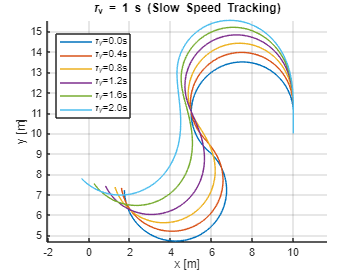


% 2. τ_v = 1 s (slow speed tracking)
figure; hold on; grid on; axis equal;
title('\tau_v = 1 s (Slow Speed Tracking)');
xlabel('x [m]'); ylabel('y [m]');

for tau_g = tau_g_list
    q = [10; 10; pi/2; 0; v_cmd];
    trace = zeros(steps+1, 2);
    trace(1,:) = q(1:2).';

    for k = 1:steps
        gamma_d = gamma_d_profile(t(k));
        u = [gamma_d, v_cmd];
        q = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_g, 1);
        trace(k+1,:) = q(1:2).';
    end
    plot(trace(:,1), trace(:,2), 'DisplayName', sprintf('\\tau_{\\gamma}=%.1fs', tau_g));
end
legend('Location','best');

#### The two figures above show how the robot's motion is affected by steering and speed lags.

#### Case 1: τ_v = 0 (Instantaneous Speed Tracking)

#### - The only delay comes from the steering actuator (τ_γ).

#### - As τ_γ increases, the robot takes longer to reach the full steering input, which causes wider turns and less sharp transitions.

#### - Low τ_γ (e.g. 0 s or 0.4 s) gives precise, sharp trajectories.

#### Case 2: τ_v = 1 s (Delayed Speed Tracking)

####  - Now both speed and steering have lag.

####  - The paths are generally smoother, but the delay causes overshoot and asymmetry.

####  - Turns are further rounded because the robot is slower to accelerate/decelerate and cannot make tight curves quickly enough.